clc;clear;
% 
% robot=importrobot('ur5_InverseKinematic.urdf');
% % showdetails(robot);
% % 
% % randConfig = robot.homeConfiguration
% % % ey
% % tform = getTransform(robot,randConfig,'EndEffort','base_link')
% % show(robot,randConfig);
% 
% tform=[eul2rotm([-pi/3 0 0])*eul2rotm([-pi/2 -pi/2 0]) [0.8;0.2;0];0 0 0 1]
% 
% 
% 
% ik = inverseKinematics('RigidBodyTree',robot);
% weights = [0.25 0.25 0.25 1 1 1];
% initialguess = robot.homeConfiguration;
% [configSoln,solnInfo] = ik('EndEffort',tform,weights,initialguess);
% show(robot,configSoln);



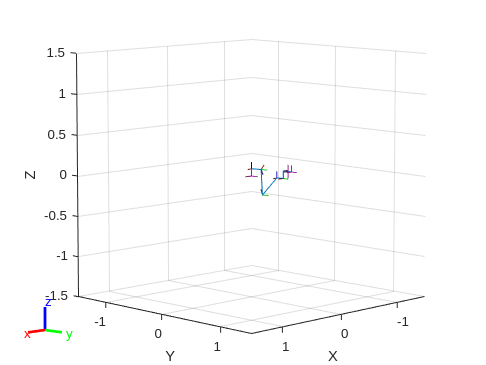


Input=[-0.6 0.1 0 0 0 0];
Local_XYZ=[Input(1);Input(2);Input(3)];
ypr=[Input(4) Input(5) Input(6)];

ur5=importrobot('ur5_InverseKinematic.urdf');
tform=[eul2rotm(ypr)*eul2rotm([-pi/2 -pi/2 0]) Local_XYZ;0 0 0 1];

ik = inverseKinematics('RigidBodyTree',ur5);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = ur5.homeConfiguration;
[configSol,solnInfo] = ik('EndEffort',tform,weights,initialguess);
show(ur5,configSol);

goalConfig=[configSol(1).JointPosition,configSol(2).JointPosition,configSol(3).JointPosition,configSol(4).JointPosition,...
    configSol(5).JointPosition,configSol(6).JointPosition]

goalConfig =     0.2529    2.1634    1.4228   -0.4446   -0.2529   -3.1416



if strcmp(solnInfo.Status,'success')

startConfig=[0 0 0 0 0 0];
rrt = manipulatorRRT(ur5,{});
rrt.MaxIterations=165;
rrt.EnableConnectHeuristic
path = plan(rrt,startConfig,goalConfig)
end

ans = logical
   1


path =          0         0         0         0         0         0
    0.0028   -0.0313   -0.0358    0.0448   -0.0538    0.0532
    0.2529    2.1634    1.4228   -0.4446   -0.2529   -3.1416
